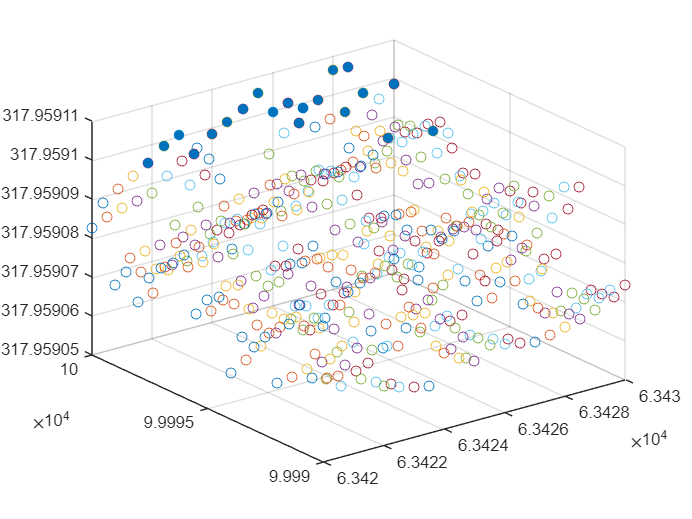

etap=[63420:0.5:63430];
etar=[99990:0.5:100000];
plist=zeros(21,21);
figure(1);
for j=1:21
for i = 1:21
p=powerp2(etap(i),etar(j));
plist(i,j)=p;
%plist_k(i,j)=i;plist_a(i,j)=j;
scatter3(etap(i),etar(j),p)
hold on
end
end

[B,IX] = sort(plist(:),'descend');
[I,J] = ind2sub(size(plist),IX) ;
scatter3(etap(I(1:20)),etar(J(1:20)),B(1:20),'filled')
hold off 

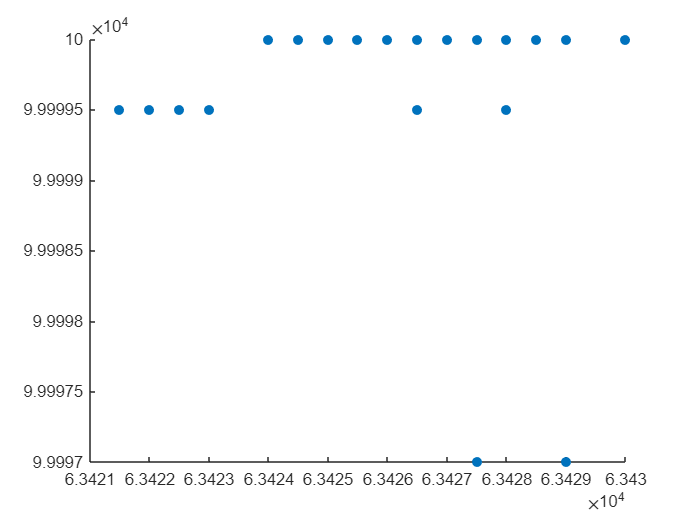


figure(2);
figure2=scatter(etap(I(1:20)),etar(J(1:20)),'filled');

[m,im]=max(plist);
[m2,im2]=max(m);
i=im(im2);
j=im2;
etap_index=etap(i)

etap_index = 63428

etar_index=etar(j)

etar_index = 100000


% plot(knp,p,'o-','MarkerSize',3)
% hold on
% [b,i]=sort(p);
% plot(knp(i(end-9:end)),b(end-9:end),'*','MarkerSize',15)
% max=sum(b(end-9:end))/10;
% index=sum(knp(i(end-9:end)))/10;








function p=powerp2(etap,etar)
V=(4866+2433)/1025; 
V1=1/3*pi*0.8; 
x0=-(V-V1)/pi+1.4;
z0=0.5-2433*9.8/80000;
b0=0;a0=0;
w=1.9806;
x1=0;z1=0;b1=0;a1=0;
%隔离法
[~,xz1]=ode45(@(t,xz1)odefun_q4(t,xz1,etap,etar),[0:0.2:40*2*pi/w],[x0;b0;z0;a0;x1;b1;z1;a1]);
vz=xz1(:,7);
va=xz1(:,8);
fix1=fix(20*2*pi/w);fix2=fix(40*2*pi/w);
square=abs(vz(fix1*5:fix2*5)).^2*etap+abs(va(fix1*5:fix2*5)).^2*etar; %%取20-60s稳定后的值来计算平均做功
area=1:(-fix1+fix2)*5;
for i=1:-fix1*5+fix2*5
area(1,i)=(square(i,1)+square(i+1,1))*0.1;
end
p=sum(area)/(20*2*pi/w);
end